# How to call Python from MATLAB

clear
close all

pyenv

ans =   PythonEnvironment with properties:

          Version: "3.8"
       Executable: "/Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2022-2023/CMEPDA/MedPhys/L8_code/matlab_python/v_env_matlab/bin/python3"
          Library: "/Library/Frameworks/Python.framework/Versions/3.8/lib/libpython3.8.dylib"
             Home: "/Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2022-2023/CMEPDA/MedPhys/L8_code/matlab_python/v_env_matlab"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "15206"
      ProcessName: "MATLAB"


pyenv('Version','/Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2022-2023/CMEPDA/MedPhys/L8_code/matlab_python/v_env_matlab/bin/python3')

ans =   PythonEnvironment with properties:

          Version: "3.8"
       Executable: "/Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2022-2023/CMEPDA/MedPhys/L8_code/matlab_python/v_env_matlab/bin/python3"
          Library: "/Library/Frameworks/Python.framework/Versions/3.8/lib/libpython3.8.dylib"
             Home: "/Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2022-2023/CMEPDA/MedPhys/L8_code/matlab_python/v_env_matlab"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "15206"
      ProcessName: "MATLAB"


py.help('len')

Help on built-in function len in module builtins:

len(obj, /)
    Return the number of items in a container.



py.os.listdir(".")

ans =   Python list with values:

    ['.DS_Store', 'How_to_call_Python_from_MATLAB.mlx', 'some_python_processing.py', 'some_matlab_processing.m', '__pycache__', 'How_to_call_MATLAB_from_Python.ipynb', '.ipynb_checkpoints', 'v_env_matlab']

    Use string, double or cell function to convert to a MATLAB array.


py.list({'This','is a','list'}) 

ans =   Python list with values:

    ['This', 'is a', 'list']

    Use string, double or cell function to convert to a MATLAB array.


py.math.sqrt(3)

ans = 1.7321

x = rand(2,2);           % MATLAB array
y = py.numpy.array(x);   % numpy array

IM = rand(10)

IM =     0.6892    0.0782    0.2599    0.5499    0.1839    0.3692    0.5752    0.6477    0.7802    0.8176
    0.7482    0.4427    0.8001    0.1450    0.2400    0.1112    0.0598    0.4509    0.0811    0.7948
    0.4505    0.1067    0.4314    0.8530    0.4173    0.7803    0.2348    0.5470    0.9294    0.6443
    0.0838    0.9619    0.9106    0.6221    0.0497    0.3897    0.3532    0.2963    0.7757    0.3786
    0.2290    0.0046    0.1818    0.3510    0.9027    0.2417    0.8212    0.7447    0.4868    0.8116
    0.9133    0.7749    0.2638    0.5132    0.9448    0.4039    0.0154    0.1890    0.4359    0.5328
    0.1524    0.8173    0.1455    0.4018    0.4909    0.0965    0.0430    0.6868    0.4468    0.3507
    0.8258    0.8687    0.1361    0.0760    0.4893    0.1320    0.1690    0.1835    0.3063    0.9390
    0.5383    0.0844    0.8693    0.2399    0.3377    0.9421    0.6491    0.3685    0.5085    0.8759
    0.9961    0.3998    0.5797    0.1233    0.9001    0.9561    0.7317    0.6256    0.

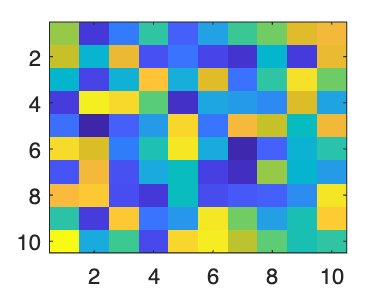

imagesc(IM)

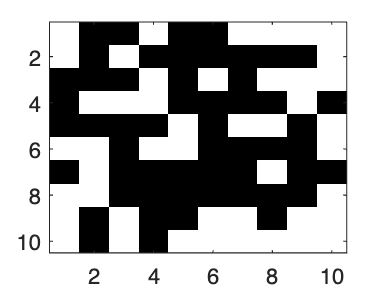

IM_th = IM > 0.5;
imagesc(IM_th); colormap gray

py.importlib.import_module('some_python_processing')

ans =   Python module with properties:

    im_to_mask: [1×1 py.function]
            np: [1×1 py.module]

    <module 'some_python_processing' from '/Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2022-2023/CMEPDA/MedPhys/L8_code/matlab_python/some_python_processing.py'>


Im_p = py.numpy.array(IM)

Im_p =   Python ndarray:

    0.6892    0.0782    0.2599    0.5499    0.1839    0.3692    0.5752    0.6477    0.7802    0.8176
    0.7482    0.4427    0.8001    0.1450    0.2400    0.1112    0.0598    0.4509    0.0811    0.7948
    0.4505    0.1067    0.4314    0.8530    0.4173    0.7803    0.2348    0.5470    0.9294    0.6443
    0.0838    0.9619    0.9106    0.6221    0.0497    0.3897    0.3532    0.2963    0.7757    0.3786
    0.2290    0.0046    0.1818    0.3510    0.9027    0.2417    0.8212    0.7447    0.4868    0.8116
    0.9133    0.7749    0.2638    0.5132    0.9448    0.4039    0.0154    0.1890    0.4359    0.5328
    0.1524    0.8173    0.1455    0.4018    0.4909    0.0965    0.0430    0.6868    0.4468    0.3507
    0.8258    0.8687    0.1361    0.0760    0.4893    0.1320    0.1690    0.1835    0.3063    0.9390
    0.5383    0.0844    0.8693    0.2399    0.3377    0.9421    0.6491    0.3685    0.5085   

py.help('some_python_processing')

Help on module some_python_processing:

NAME
    some_python_processing

FUNCTIONS
    im_to_mask(A, th=0.5)
        This function applies the threshold th to convert the A image into a mask

FILE
    /Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2022-2023/CMEPDA/MedPhys/L8_code/matlab_python/some_python_processing.py




py.help('some_python_processing.im_to_mask')

Help on function im_to_mask in some_python_processing:

some_python_processing.im_to_mask = im_to_mask(A, th=0.5)
    This function applies the threshold th to convert the A image into a mask



IM_th_py = py.some_python_processing.im_to_mask(Im_p, 0.5) 

IM_th_py =   Python ndarray:

   1   0   0   1   0   0   1   1   1   1
   1   0   1   0   0   0   0   0   0   1
   0   0   0   1   0   1   0   1   1   1
   0   1   1   1   0   0   0   0   1   0
   0   0   0   0   1   0   1   1   0   1
   1   1   0   1   1   0   0   0   0   1
   0   1   0   0   0   0   0   1   0   0
   1   1   0   0   0   0   0   0   0   1
   1   0   1   0   0   1   1   0   1   1
   1   0   1   0   1   1   1   1   1   1

    Use details function to view the properties of the Python object.

    Use logical function to convert to a MATLAB array.


IM_th_mat = logical(IM_th_py);

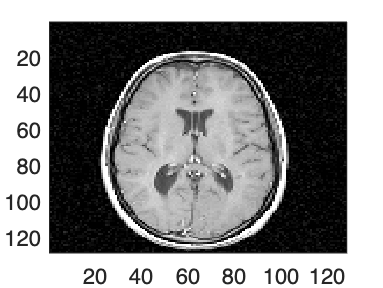

IM= imread("/Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2022-2023/CMEPDA/MedPhys/L2_code/MRIslice_noise.png");
imagesc(IM)

IM_p= py.numpy.array(IM);
IM_th_py = py.some_python_processing.im_to_mask(IM_p, 10)

IM_th_py =   Python ndarray:

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

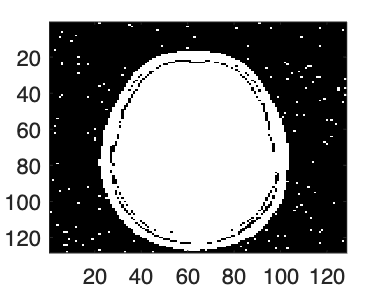

IM_th_mat = logical(IM_th_py);
imagesc(IM_th_mat)